# ASTE 583 Final Project

## Introduction

The ASTE 583 Final Project focuses on Lunar Trailblazer, a satellite which lost contact with earth shortly after launch in February, 2025. **Insert more detailed problem statement here.**

 All scripts, functions, reports and other deliverables were written by Varsha Krishnakumar and Nicholas Mellanby.

## Section 1: Problem Initialization

clear
clc

% Call Project Init Function
[params,sc,st,X0,P0] = projectInit();

% Init Times for Initial Detection, LTM, and LCM
[ET0,LTM,LCM] = initTime();


## Section 2: Integrate Dynamics (Sun-Centered EMO2000)

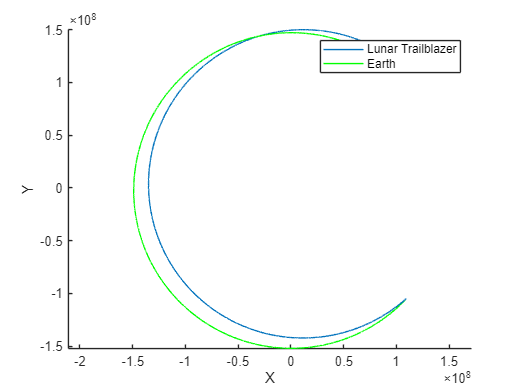

%Set Options
options = odeset('RelTol',1e-10,'AbsTol',1e-10);
step = 1800; %30 min intervals

%Set X0 pre LTM
X0preLTM= [X0;reshape(eye(10),100,1)];

%Integrate to LTM
[TpreLTM,XpreLTM] = ode45(@projectDynamics,ET0:step:LTM,X0preLTM,options,params,sc);

%Set X0 post LTM
X0postLTM = [XpreLTM(end,1:10)';reshape(eye(10),100,1)];

%Apply deltaV
deltaVLTM = [0.6931075; -0.8462091; 0.0956979];
X0postLTM(4:6) = X0postLTM(4:6) + deltaVLTM;

%Integrate from LTM to 251 days - LTM occurs after 15 days, so add 236 days to trajectory
TOF = 236*24*3600; %236 days in seconds
[TpostLTM,XpostLTM] = ode45(@projectDynamics,LTM:step:LTM+TOF,X0postLTM,options,params,sc);

%Combine Results
Xtotal = [XpreLTM(:,1:6);XpostLTM(:,1:6)];
Ttotal = [TpreLTM;TpostLTM];

%Plot Sun-Centric Trajectory
figure(1)
hold on
plot3(Xtotal(:,1),Xtotal(:,2),Xtotal(:,3))
axis('equal')
xlabel("X")
ylabel("Y")

%Retrieve Earth Position at Each Time Step
xEarth = cspice_spkezr('Earth',Ttotal(:,1)', 'ECLIPJ2000', 'NONE','Sun');
plot3(xEarth(1,:),xEarth(2,:),xEarth(3,:),'-g')

%Add Legend
legend("Lunar Trailblazer","Earth")

## Section 3: Convert Plot to Earth Centered EMO2000

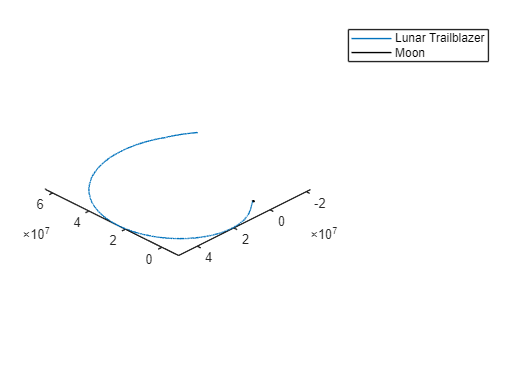

% Plot Relative Earth Motion
XrelEarth = Xtotal(:,1:6) - xEarth';
figure(2);
hold on
plot3(XrelEarth(:,1),XrelEarth(:,2),XrelEarth(:,3))
view([-135 30])

%Add Moon
%Retrieve Earth Position at Each Time Step
xMoon = cspice_spkezr('Moon',Ttotal(:,1)', 'ECLIPJ2000', 'NONE','Earth');
plot3(xMoon(1,:),xMoon(2,:),xMoon(3,:),'-k')

axis("equal")
legend("Lunar Trailblazer","Moon")

%Verify Lunar Flyby
flybyDistance = zeros(length(XrelEarth),1);
minflybyDist = 10^9; %Unrealistic flyby distance number
timeminflybyDist = 0; %Unrealistic flyby time
for i = 1:length(XrelEarth)
    flybyDistance(i,1) = norm(XrelEarth(i,1:3) - xMoon(1:3,i)');
    if(flybyDistance(i,1) < minflybyDist)
        minflybyDist = flybyDistance(i,1);
        timeminflybyDist = (Ttotal(i)-ET0)/(24*3600); %Time since ET0 in days
    end
end
%figure(3);
%plot(Ttotal,flybyDistance)
disp("Closest Approach of Lunar Trailblazer to the Moon is " + min(flybyDistance) + " km at " + timeminflybyDist + " days.")

Closest Approach of Lunar Trailblazer to the Moon is 1893.025 km at 250.5417 days.


## Section 4: Plot Ground Track

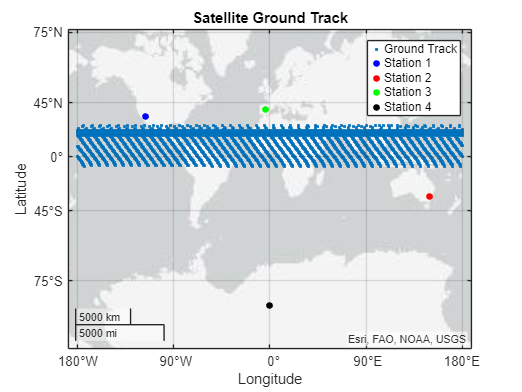

% Convert Relative Position Vectors to EME
R_EMOtoEME = inv(params.R_EMEtoEMO);
XrelEarthEME = zeros(length(Ttotal),6);
for i = 1:length(Ttotal)
    XrelEarthEME(i,:) = [(R_EMOtoEME*XrelEarth(i,1:3)')',(R_EMOtoEME*XrelEarth(i,4:6)')'];
end

plotGroundTrack(Ttotal,XrelEarthEME,params,st);